# Presentación Final (Cinemática Diferencial de Piernas)

### Arick Morelos del Campo | A01735692

**Obtener **la matriz de  transformación **homogénea global T, empleando variables simbólicas **de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base). Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final

**Desarrollar** el modelo de **cinemática diferencial simbólica** para cada uno de los sistemas descritos anteriormente y obtener los vectores de la **velocidad angular y velocidad lineal** aplicando variables simbólicas para su análisis en cada caso.

**Implementar **el código requerido para generar el cálculo de las matrices **homogéneas simbólicas (H1, H2, H3, etc.),** la matriz de **transformación simbólica (T)** y los vectores de **velocidades simbólicas (v, w)** de cada sistema.

#### 1:

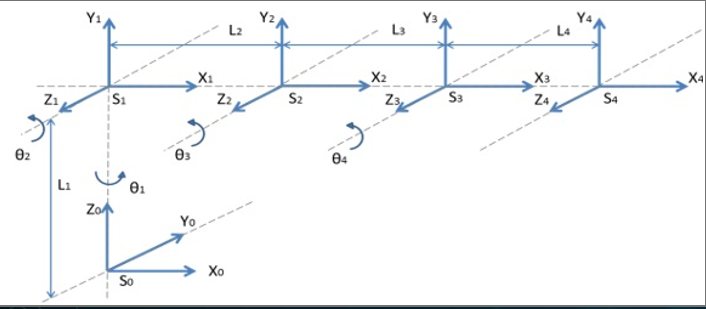

%Limpieza de pantalla
clear all
close all
clc
l1 = 1; l2 = 1; l3 = 1; l4 = 1;
%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2),  [0 0 l1]);
H2=SE3([l2 0 0]);
H3=SE3([l3 0 0]);
H4=SE3([l4 0 0]);

H20= H1*H2;
H30= H20*H3;
H40= H30*H4;%Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 0 1 2 3 ];
y=[0 0 0 0 0 ];
z=[0 1 1 1 1 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 6 -1 6 -1 2]);
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2]);
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2]);
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2]);
  disp(H30);

    1         0         0         2
    0         0        -1         0
    0         1         0         1
    0         0         0         1


 %pause;
  tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2]);
  disp(H40);

    1         0         0         3
    0         0        -1         0
    0         1         0         1
    0         0         0         1


#### 2:

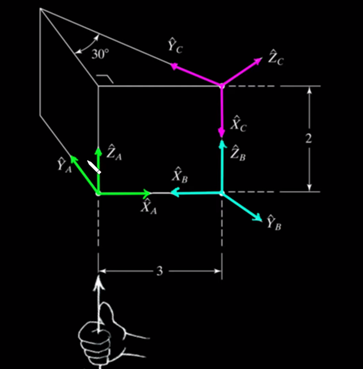

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotz(pi), [3 0 0]);
H2=SE3(roty(pi/2), [0 0 0]);
H3=SE3(rotx(150*pi/180), [-2 0 0])

 

H3 = 
         1         0         0        -2
         0   -0.8660   -0.5000         0
         0    0.5000   -0.8660         0
         0         0         0         1



H20= H1*H2;
H30= H20*H3 %Matriz de transformación homogenea global de 3 a 0 

 

H30 = 
         0   -0.5000    0.8660         3
         0    0.8660    0.5000         0
        -1         0         0         2
         0         0         0         1



%Coordenadas de la estructura de translación y rotación
x=[0 3 3 0 0 0     0     0 0     3];
y=[0 0 0 0 0 5.196 5.196 0 5.196 0];
z=[0 0 2 2 0 0     2     2 2     2];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2]);
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2]);
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2]);
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2]);
  disp(H30);

     0      -0.5     0.866         3
     0     0.866       0.5         0
    -1         0         0         2
     0         0         0         1


####  3:

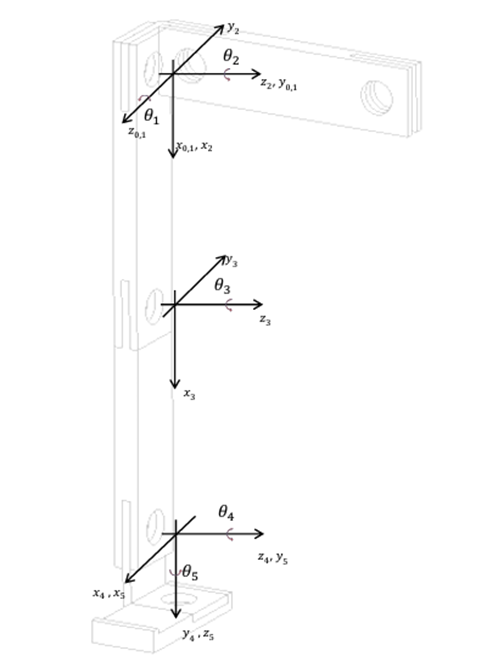

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3(roty(pi/2), [0 0 0]);
H1=SE3(rotx(-pi/2), [0 0 0]);
H2=SE3(roty(0), [2 0 0]);
H3=SE3(rotz(-pi/2), [2 0 0]);

%Matriz de transformación homogenea global de 3 a 0 
H20=H1*H2;
H30= H20*H3;

%Coordenadas de la estructura de translación y rotación
x=[0 2 4];
y=[0 0 0];
z=[0 0 0];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 6 -1 6 -1 6]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 6 -1 6 -1 6])                                    

% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H1,'rgb','axis', [-1 6 -1 6 -1 6])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H20, H30,'rgb','axis', [-1 6 -1 6 -1 6])

  disp(H30)
  disp(H3)


#### 4:

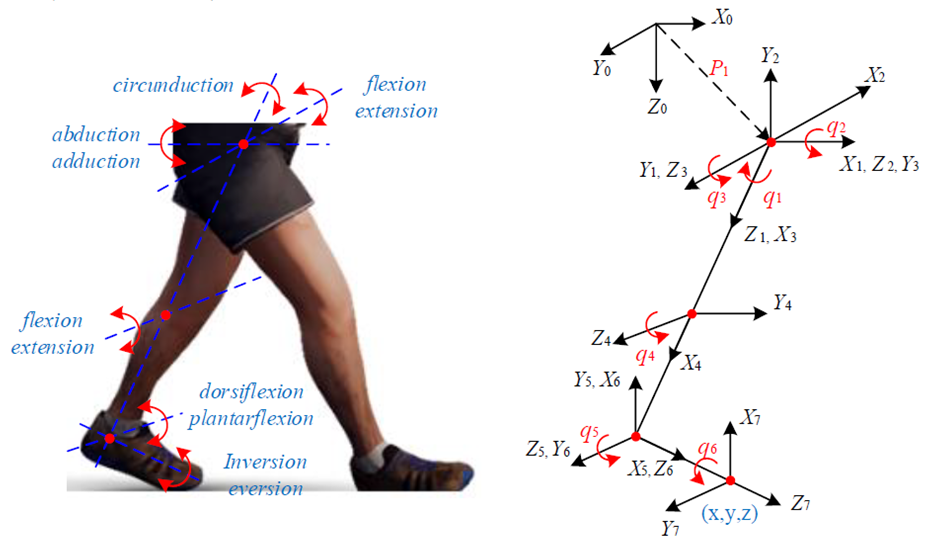

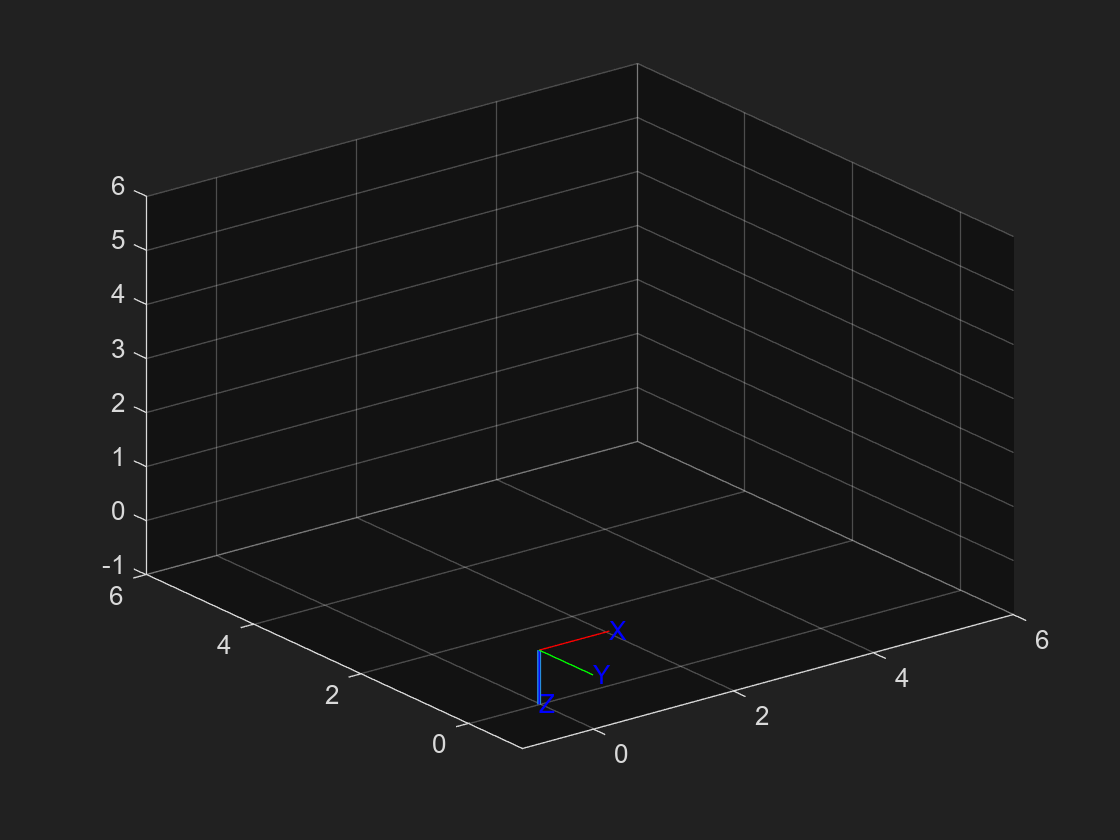

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3(rotx(pi), [0 0 0]);
H1=SE3(rotz(pi/2), [0 0 0]);
H2=SE3(rotx(pi/2), [0 0 0]);
H3=SE3(rotz(-pi/2), [0 0 0]);
H4=SE3(rotx(pi/2), [0 0 0]);
H5=SE3(rotz(0), [3 0 0]);
H6=SE3(rotz(pi/2), [3 0 0]);
H7=SE3(rotz(pi/2), [0 0 0]);
H8=SE3(rotx(pi/2), [0 0 0]);
H9=SE3(rotz(0), [0 0 3]);

%Matriz de transformación homogenea global de 3 a 0 
H20=H1*H2;
H30= H20*H3;
H40=H30*H4;
H50=H40*H5;
H60=H50*H6;
H70=H60*H7;
H80=H70*H8;
H90=H80*H9;

%Coordenadas de la estructura de translación y rotación
x=[0 0 0 3];
y=[0 0 0 0];
z=[0 -3 -6 -6];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 6 -1 6 -1 6]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 6 -1 6 -1 6])

 pause;
  tranimate(H0, H1,'rgb','axis', [-1 6 -1 6 -1 6])

 pause;
 tranimate(H1, H20,'rgb','axis', [-1 6 -1 6 -1 6])

 pause;
  tranimate(H20, H30,'rgb','axis', [-1 6 -1 6 -1 6])

 pause;
  tranimate(H30, H40,'rgb','axis', [-1 6 -1 6 -1 6])

 pause;
  tranimate(H40, H50,'rgb','axis', [-1 6 -1 6 -1 6])

 pause;
  tranimate(H50, H60,'rgb','axis', [-1 6 -1 6 -1 6])

 pause;
  tranimate(H60, H70,'rgb','axis', [-1 6 -1 6 -1 6])
 
 pause;
  tranimate(H70, H80,'rgb','axis', [-1 6 -1 6 -1 6])
 
 pause;
  tranimate(H80, H90,'rgb','axis', [-1 6 -1 6 -1 6])

  disp(H90)
  disp(H9)


%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t a1 a2 a3 l1 l2

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3];

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
GDL= size(RP,2);
GDL_str= num2str(GDL);

  y_transf= [0 0 1; 
             0 1 0;
            -1 0 0];

  x_transf= [1  0       0;  
             0 -0.8660 -0.5000 ;
             0  0.5    -0.8660];  

 Rot2= y_transf*x_transf;

rotacion_x= [1        0         0;
             0 cos(th1) -sin(th1);
             0 sin(th1)  cos(th1)];
rotacion_y= [cos(th2)  0 sin(th1);
                    0  1        0;
            -sin(th2)  0 cos(th2)];
rotacion_z= [cos(th3) -sin(th3)  0;
             sin(th3)  cos(th3)  0;
              0         0        1];
% 
%  transfor_2= x_transf*rotacion_z;

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1);l1*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= rotacion_z.*rotacion_y.*rotacion_x;

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th4);l2*sin(th4);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th4) -sin(th4)  0;
           sin(th4)  cos(th4)  0;
           0         0        1];

rotacion_y= [cos(th5)  0 sin(th5);
                    0  1        0;
            -sin(th5)  0 cos(th5)];
rotacion_z= [cos(th6) -sin(th6)  0;
             sin(th6)  cos(th6)  0;
              0         0        1];
%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [l2*cos(th5);l2*sin(th6);0];
%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)= rotacion_z.*rotacion_y;
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp')
%pretty(V);
disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp')
%pretty(W);